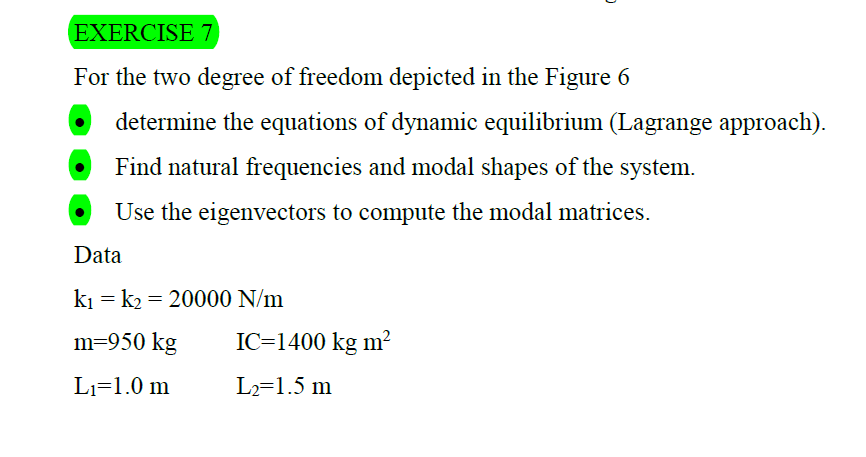

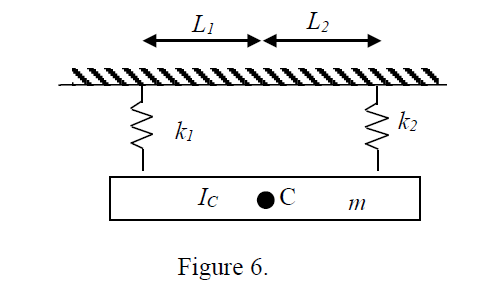

clear all
clc

m=950;
l1=1;
l2=1.5;

Ic=1.4*10^3;
k1=20*10^3;
k2=k1;

M=[m 0;0 Ic];
K=[k1+k2 k1*l1-k2*l2;
  k1*l1-k2*l2 k1*l1^2+k2*l2^2];


%solve the eigenproblem det(K-w^2*M)=0, obtaining two values of w^2
syms w x y

% w=double(solve(det(K-w^2*M==0)))
solve((K-w^2*M)*[x y]'==0)

ans = struct with fields:
    x: [1×1 sym]
    y: [1×1 sym]


Unrecognized function or variable 'teta10'.


%% autovettori


%Compute modal mass, modal stiffness and modal forces
% Mm=phi'*M*phi
% Km=phi'*K*phi
% 
% phi
% 
